# Simulations Runs (Learning N Memories Alternating)

## Creating the network and stimulation protocol

clc; clear;

% Create the network
InstanciateIzhikevichNet();
mynet.stimulation = true;


N_mems = 10;

stims = [];
for i = 1:N_mems
    stims = [stims, Stimulation(mynet, N_mems*100, 2, 30, 50, (i-1)*100 + 10)];
end

## Learning the Memories 

for i = 1:10
    mynet.run(100*N_mems*100);
end
save(mynet.RecordingDirectory + filesep + "stims.mat")

## getting firings rasters for each memory in time (just first spikes)

% ``load('C:\Users\SeyedArshia.Razavi\Desktop\StableMemoriesWithUnstableSynapses\Matlab version\IzhikevichNetworkWithPlasticity\NetwerkLevel\TimeDelayRepresentation\Data\Oct_22_2024_23_28_20\stims.mat')
ff = nan(N_mems, 1000, 400);

for i = 1:10
    load(mynet.RecordingDirectory + filesep + "Patch" + num2str(i) + ".mat", ['data' num2str(i)]);
    eval("firings = data" + num2str(i) + ".firings; clear data" + num2str(i));
    for trial = (1:100*N_mems) + (i-1)*100*N_mems
        index = (firings(1, :) > (trial-1)*100) & (firings(1, :) < trial*100);
        t_firings = firings(:, index);
        f = FirstSpikeFirings(t_firings);

        m = mod(trial, N_mems); tr = ceil(trial/N_mems);
        m(m == 0) = N_mems;
        ff(m, tr, f(2, :)) = mod(f(1, :), 100);
    end
end

## Checking if the protocol is correct

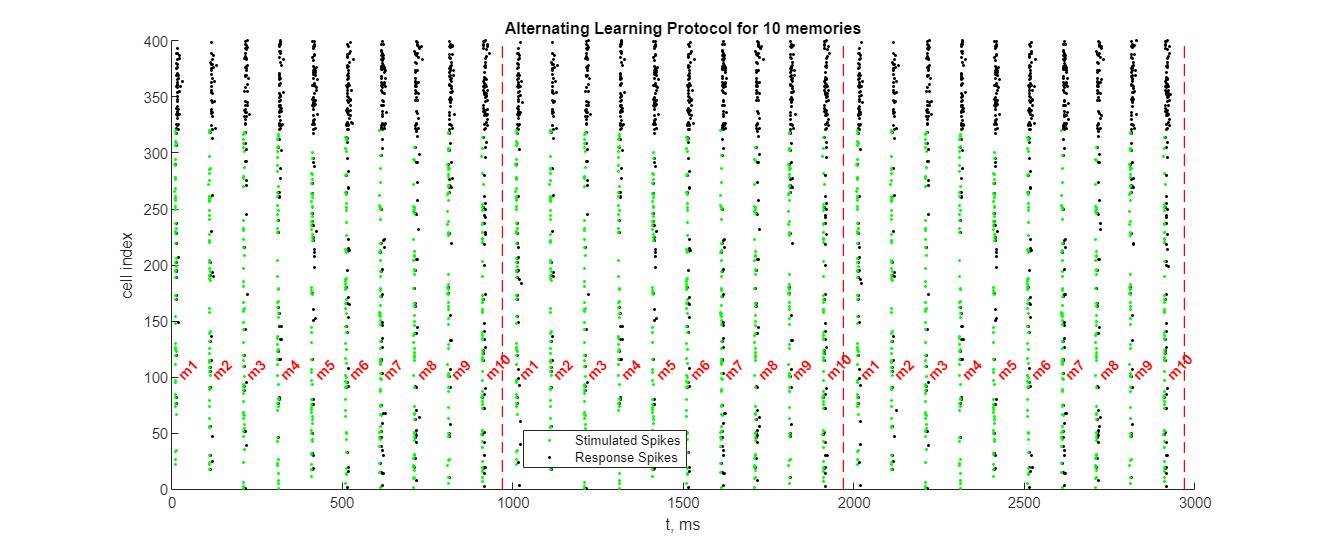

N_periods = 3;
load(mynet.RecordingDirectory + filesep + "Patch1.mat", 'data1');
firings = data1.firings; clear data1;

fig = figure; fig.Position(3:4) = [1200 500]; hold on;
for iter = 1:N_periods
    plot(N_mems*100*iter*[1 1]-30, [0 400], 'r--', LineWidth=1, HandleVisibility='off')
    for m = 1:N_mems
        index = (firings(1, :) > (iter-1)*N_mems*100 + (m-1)*100) & (firings(1, :) < (iter-1)*N_mems*100 + m*100);
        t_firings = firings(:, index);
        f = FirstSpikeFirings(t_firings); 
        plot(t_firings(1, :), t_firings(2, :), 'k.', HandleVisibility='off')
        
        scatter(squeeze(ff(m, iter, stims(m).pattern_indices)) + (iter-1)*N_mems*100 + (m-1)*100, stims(m).pattern_indices , 'g.', HandleVisibility='off')
        text(((iter-1)*N_mems*100 + (m-1)*100 + 25), 100, ['m' num2str(m)], 'Color', 'r', 'FontWeight','bold', 'Rotation', 45);
    end
end
scatter([], [], 'g.', DisplayName='Stimulated Spikes');
scatter([], [], 'k.', DisplayName='Response Spikes');

legend(Location='best')
xlabel("t, ms")
ylabel("cell index")
title(['Alternating Learning Protocol for ' num2str(N_mems) ' memories'])

## Visualizing a single memory evolution

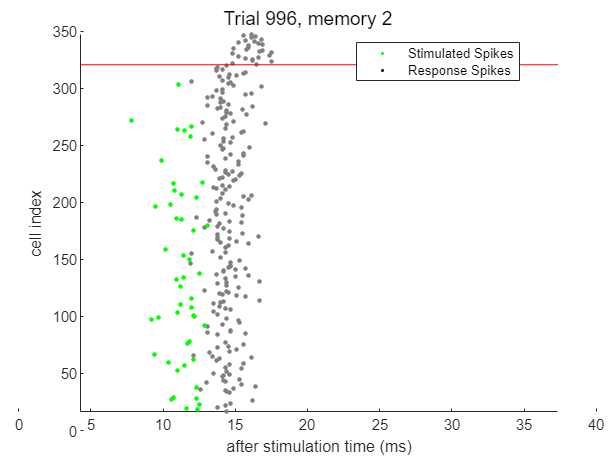

m = randi(N_mems);
f = squeeze(ff(m, :, :));


fig = figure(); hold on; t_max = 40; 
colors = 0.5*repmat([1 1 1], 400, 1); colors(stims(m).pattern_indices, :) = repmat([0 1 0], 50, 1);
sc = scatter(f(1 ,:), 1:400, 10, colors, 'filled'); plot([0 t_max], 320.5*[1 1], 'r-', LineWidth=0.1, HandleVisibility='off');
xlim([0 t_max]); xlabel("after stimulation time (ms)"); ylabel("cell index");
scatter([], [], 'g.', Displayname = "Stimulated Spikes"); scatter([], [], 'k.', Displayname = "Response Spikes"); legend(Location='best'); hold off;
for trial = 1:5:1000
    sc.XData = f(trial, :);
    sc.HandleVisibility = 'off';
    sgtitle(['Trial ' num2str(trial) ', memory ' num2str(m)])
    drawnow;
end

## Convergence of a memory in learning + Comparison of different memories in time

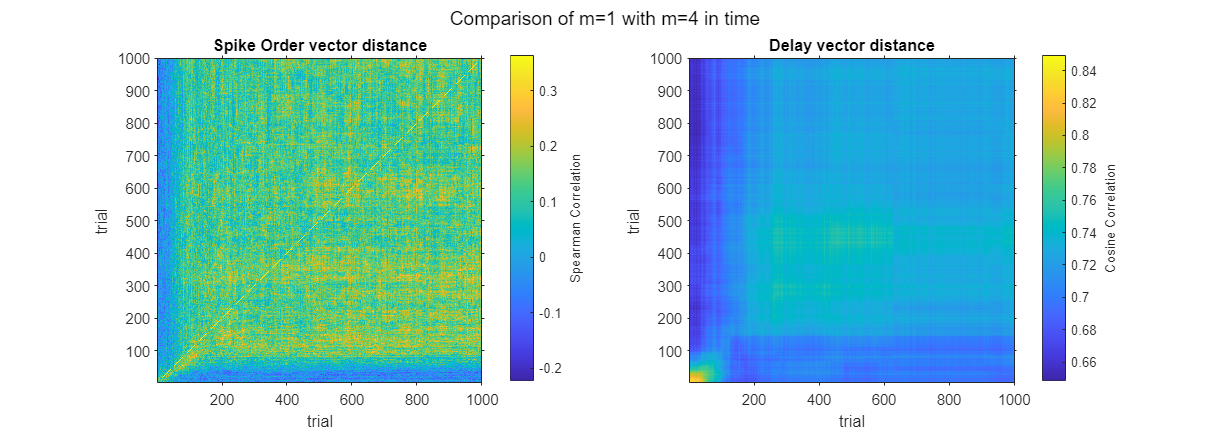

m1 = randi(N_mems); m2 = randi(N_mems);
f1 = squeeze(ff(m1, :, :));
f2 = squeeze(ff(m2, :, :));

% f(isnan(f)) = 100 + 10*randn(length(f(isnan(f))), 1);
f1(isnan(f1)) = 100 + 5*randn(length(f1(isnan(f1))), 1);
f2(isnan(f2)) = 100 + 5*randn(length(f2(isnan(f2))), 1);

fig = figure; fig.Position(3:4) = [1100 400]; 
if m1 == m2
    sgtitle("Convergence of memory " + num2str(m1) + " in learning process")
else
    sgtitle(['Comparison of m=' num2str(m1) ' with m=' num2str(m2) ' in time'])
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1, 2, 1)
% [~, order] = sort(f, 2);
[~, order1] = sort(f1, 2);
[~, order2] = sort(f2, 2);

distmat = 1- pdist2(order1, order2, "spearman");
distmat(logical(eye(length(distmat)))) = max(distmat(logical(triu(distmat,1))));

imshow(distmat', [], 'InitialMagnification', 'fit')
colormap("parula")
% clim([-0.2 1]);

cb = colorbar(); cb.Label.String = "Spearman Correlation";
axis on; xlabel("trial"); ylabel("trial");
title("Spike Order vector distance")
set(gca, 'ydir', 'normal'); 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1, 2, 2)
distmat = 1- pdist2(f1, f2, "cosine");
distmat(logical(eye(length(distmat)))) = max(distmat(logical(triu(distmat,1))));

imshow(distmat', [], 'InitialMagnification', 'fit')
colormap("parula")
% clim([0 1]);

cb = colorbar(); cb.Label.String = "Cosine Correlation";
axis on; xlabel("trial"); ylabel("trial");
title("Delay vector distance")
set(gca, 'ydir', 'normal'); 

## Lets's retrieve the memories by partial stimulation

alpha = 0.3; % The percentage of those 50 to call for memory retrieval 
N_retrievals = 100;
N_rands = 100;

N_mems = 50;
load(mynet.RecordingDirectory + filesep + "Patch2550.mat", 'obj');

mynet = obj;
mynet.sampling = false;
mynet.STDP = false;
ff_partial = nan(N_mems, N_retrievals, 400);
ff_partial_null = nan(N_rands, 400);

mynet.saveSimulation = false;

bar = waitbar(0, "please wait ...");
bar.Position(1:2) = [500 500];
for iter = 1:N_retrievals
    waitbar((iter-1)/(N_retrievals+N_rands), bar, sprintf("Sampling\n Partial Recall  %d/%d\n Random Recall %d/%d", iter, N_retrievals, 0, N_rands));
    mynet.PatchNumber = 10 + 1;
    for m = 1:N_mems
        stim = stims(m).copy();
        stim.Ncells = ceil(alpha*stims(m).Ncells);
        sub_set = randperm(stims(m).Ncells); sub_set = sub_set(1:stim.Ncells);
        stim.pattern_indices = stim.pattern_indices(sub_set);
        stim.pattern_timings = stim.pattern_timings(sub_set);
        stim.interval = 100;
        stim.start_time = 10;
        stim.pattern_timings = mod(stim.pattern_timings, 100);
        stim.ConstructStimCurrent();
    
        mynet.stims = [stim];
        mynet.run(100);
        
        % load(mynet.RecordingFile, ['data' num2str(mynet.PatchNumber-1)]);
        % eval(['f = data' num2str(mynet.PatchNumber-1) '.firings; f(1,:) = mod(f(1, :), 100);'])
        f = mynet.firings'; f(1, :) = mod(f(1,:), 100);
        
        ff_partial(m, iter, f(2, :)) = f(1, :);
    end
end

for iter = 1:N_rands
    waitbar((iter+N_retrievals)/(N_retrievals+N_rands), bar, sprintf("Sampling\n Partial Recall  %d/%d\n Random Recall %d/%d", N_retrievals, N_retrievals, iter, N_rands));

    stim_rand = Stimulation(mynet, 100, 2, 30, ceil(alpha*stims(1).Ncells), 10);
    mynet.stims = [stim_rand];
    mynet.run(100); f = mynet.firings'; f(1, :) = mod(f(1,:), 100);
    ff_partial_null(iter, f(2, :)) = f(1, :);
end

% for m = 1:N_mems
%     delete(mynet.RecordingDirectory + filesep + "Patch" + num2str(10+m) + ".mat");
% end
close(bar)
% save(mynet.RecordingDirectory + filesep + num2str(alpha*100) + "PercentPartialRecall.mat", 'ff_partial', "mynet", "N_retrievals", "alpha", '-mat')

## Let's Retrieve them by shuffling spike times!

N_retrievals = 200;
N_rands = 200;

load(mynet.RecordingDirectory + filesep + "Patch10.mat", 'obj');
mynet = obj;
mynet.sampling = false;
mynet.STDP = false;
mynet.saveSimulation = false;

ff_shuffle = nan(N_mems, N_retrievals, 400); 
ff_shuffle_null = nan(N_rands, 400);

bar = waitbar(0, "please wait ...");
bar.Position(1:2) = [500 500];
for iter = 1:N_retrievals
    waitbar((iter-1)/(N_retrievals+N_rands), bar, sprintf("Sampling\n Shuffled Recall  %d/%d\n Random Recall %d/%d", iter, N_retrievals, 0, N_rands));
    mynet.PatchNumber = 10 + 1;
    for m = 1:N_mems
        stim = stims(m).copy();
        sub_set = randperm(stims(m).Ncells); 
        stim.pattern_timings = stim.pattern_timings(sub_set);
        stim.interval = 100;
        stim.start_time = 10;
        stim.pattern_timings = mod(stim.pattern_timings, 100);
        stim.ConstructStimCurrent();
    
        mynet.stims = [stim];
        mynet.run(100);
        
        % load(mynet.RecordingFile, ['data' num2str(mynet.PatchNumber-1)]);
        % eval(['f = data' num2str(mynet.PatchNumber-1) '.firings; f(1,:) = mod(f(1, :), 100);'])
        f = mynet.firings'; f(1, :) = mod(f(1,:), 100);

        ff_shuffle(m, iter, f(2, :)) = f(1, :);
    end
end

for iter = 1:N_rands
    waitbar((iter+N_retrievals)/(N_retrievals+N_rands), bar, sprintf("Sampling\n Shuffle Recall  %d/%d\n Random Recall %d/%d", N_retrievals, N_retrievals, iter, N_rands));

    stim_rand = Stimulation(mynet, 100, 2, 30, stims(1).Ncells, 10);
    mynet.stims = [stim_rand];
    mynet.run(100); f = mynet.firings'; f(1, :) = mod(f(1,:), 100);
    ff_shuffle_null(iter, f(2, :)) = f(1, :);
end

% for m = 1:N_mems
%     delete(mynet.RecordingDirectory + filesep + "Patch" + num2str(10+m) + ".mat");
% end
close(bar)
% save(mynet.RecordingDirectory + filesep + "ShuffleRecall", 'ff_shuffle', "mynet", "N_retrievals", '-mat')

## Classification of Responses by Kmeans

% f = ff_shuffle;
% ff_null = ff_shuffle_null;
f = ff_partial;

Unrecognized function or variable 'ff_partial'.

ff_null = ff_partial_null;

new_f = [];
for m = 1:N_mems
    new_f = [new_f; squeeze(f(m, :, :))];
end
f = new_f;
f(isnan(f)) = 100 + 0* randn(sum(isnan(f), 'all'), 1);
ff_null(isnan(ff_null)) = 100;

trueLabels = [];
for iter = 1:N_mems
    trueLabels = [trueLabels, repmat(iter, 1, N_retrievals)];
end
trueLabels = [trueLabels, repmat(N_mems+1, 1, size(ff_null, 1))];
trueLabels = trueLabels';

% classification by kmeans
 % [~, f] = sort(f, 2);

% Perform kmeans with more precision
[predictedLabels, C] = kmeans([f; ff_null] , N_mems+1, ...
    'Replicates', 200, ...          % Run the algorithm 10 times with different initializations
    'MaxIter', 100000, ...            % Increase the maximum number of iterations for convergence
    'Distance', 'sqeuclidean', ...  % Use squared Euclidean distance (default, but customizable)
    'Display', 'final', ...
     'Start', 'plus');            % Display final output with information on convergence


[coeff, score, latent, tsquared, explained, mu] = pca([f; ff_null]);
C = (C-mu)*coeff; % rotating cluster coordiantes to the pca basis

[permpredictedLabels, perm] = matchLabels(trueLabels, predictedLabels);
% perm = perm(perm);

cmap = jet(N_mems); cmap = cmap(randperm(N_mems), :);

% figure; view(3); grid on; hold on; 
% cmap = [cmap; [0 0 0]];
% %%%%%%%%%%%%%%%%%%% Plotting Memories Recall %%%%%%%%%%%%
% scatter3(score(:, 1), score(:, 2), score(:, 3), 20, cmap(trueLabels, :), 'filled', 'HandleVisibility', "off")
% 
% scatter3(C(:, 1), C(:, 2), C(:, 3), 2000, cmap(perm, :), HandleVisibility="off")
% for m = 1:N_mems
%     scatter3([], [], [], 1, cmap(m, :), 'filled', DisplayName=['m ' num2str(m)])
% end
% 
% %%%%%%%%%%%%%%%%%%% Plotting Random Recalls %%%%%%%%%%%%
% rnd_recalls = (ff_null-mu)*coeff;
% scatter3(rnd_recalls(:, 1), rnd_recalls(:, 2), rnd_recalls(:, 3), 20, 'kh', 'filled', 'HandleVisibility', 'off')
% 
% scatter3([], [], [], 1, 'kh', 'filled', DisplayName='random recall')
% 
% 
% legend(Location='best')
% xlabel("PC1"); ylabel("PC2"); zlabel("PC3"); title("Partial Recall of Memories (" + num2str(alpha*100) + "% of Stimulation Set)")
labellist = arrayfun(@(x) [num2str(x)], 1:N_mems, 'UniformOutput', false); labellist = [labellist, "random recalls"];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
figure; hold on;plot(permpredictedLabels'+0.1, 'k.', DisplayName="Predicted Label"); plot(trueLabels-0.1, 'r.', DisplayName="True Label")
legend(Location='best'); xlabel("data points"); ylabel("Cluster Label"); ylim([0.5 N_mems+1+0.5]); yticks(1:N_mems+1);  yticklabels(labellist);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
fig = figure; fig.Position(3:4) = [1500 1500];
cm = confusionchart(labellist(trueLabels), labellist(permpredictedLabels));

cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
title('Confusion Matrix: True vs Predicted Labels');
saveas(fig, [num2str(randi(10)) '.png'])


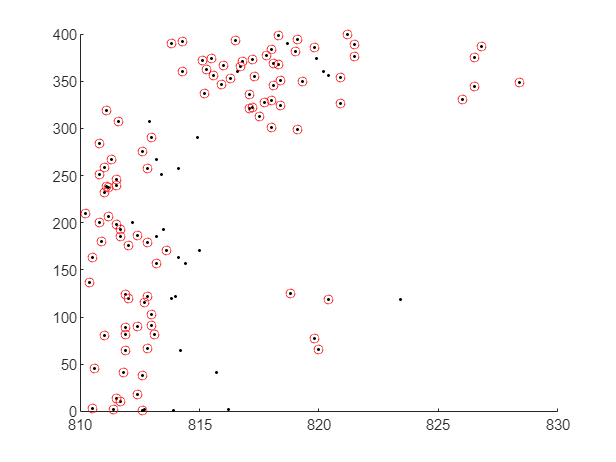

f = FirstSpikeFirings(t_firings);
figure; hold on;
plot(mod(t_firings(1, :), 100), t_firings(2, :), 'k.')
plot(f(1,:), f(2, :), 'ro')

# Functions

function new_firings = FirstSpikeFirings(firings)
    fired_cells = unique(firings(2, :));
    new_firings = [];
    for cell = fired_cells
        index = find(firings(2, :) == cell);
        if ~isempty(index)
            new_firings = [new_firings; firings(1, index(1)), cell];
        end 
    end
    new_firings = new_firings';
end

function [permutedPredLabels, perm] = matchLabels(trueLabels, predictedLabels)
    % This function permutes the predicted labels to best match the true labels.
    
    % Find the unique labels in true and predicted labels
    uniqueTrueLabels = unique(trueLabels);
    uniquePredLabels = unique(predictedLabels);
    
    % Number of unique labels
    numLabels = length(uniqueTrueLabels);
    
    % Create a confusion matrix to compute the cost of assigning each predicted
    % label to each true label.
    costMatrix = confusionmat(trueLabels, predictedLabels);
    
    % for i = 1:numLabels
    %     for j = 1:numLabels
    %         % Negative accuracy as cost (we want to maximize accuracy, so minimize cost)
    %         costMatrix(i, j) = sum((predictedLabels == uniquePredLabels(j)) & (trueLabels ~= uniqueTrueLabels(i)));
    %     end
    % end
    
    % Use the Hungarian algorithm to find the optimal assignment
    assignment = munkres(-costMatrix);  % Returns optimal assignment (permutation)
    [assignedrows,~]=find(assignment);

    % Permute predicted labels
    permutedPredLabels = predictedLabels;
    for i = 1:numLabels
        permutedPredLabels(predictedLabels == uniquePredLabels(i)) = uniqueTrueLabels(assignedrows(i));
    end

    perm = assignedrows;
end


